# **ELEN-865 Theory of Linear Control System**

# **Spring 2018**

# **Final Exam**

# **Mrinmoy Sarkar**

# **950363260**

A=[1 1;1 -2]

A =      1     1
     1    -2


B=[1;2]

B =      1
     2


C=[1 3]

C =      1     3


D=[0]

D = 0

r=0.1

r = 0.1000

Q=[1 0;0 10]

Q =      1     0
     0    10


ctrl = ctrb(A,B)

ctrl =      1     3
     2    -3


p = rank(ctrl)

p = 2

K=lqr(A,B,Q,r,0)

K =     6.5568    6.8259


## **a)**

The LQR control law is u = -KX, where K is given above.

sys = ss(A,B,C,D)


sys =
 
  A = 
       x1  x2
   x1   1   1
   x2   1  -2
 
  B = 
       u1
   x1   1
   x2   2
 
  C = 
       x1  x2
   y1   1   3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



isstable(sys)

ans = logical
   0


Acl = A-B*K

Acl =    -5.5568   -5.8259
  -12.1136  -15.6518


Bcl = [0 ; 0]

Bcl =      0
     0


sys = ss(Acl,Bcl,C,D)


sys =
 
  A = 
           x1      x2
   x1  -5.557  -5.826
   x2  -12.11  -15.65
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



isstable(sys)

ans = logical
   1


## **b)**

The open loop system is not stable but the closed loop system is stable.

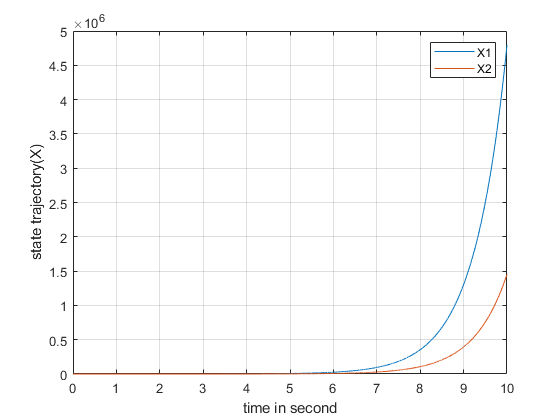

dt=0.001;
tf=10;
t=0:dt:tf;
x0=[10,5]';
x = zeros(length(t), 2);
x(1,:) = x0';
u = zeros(length(t), 1);
for i=2:length(t)
    
    xx0 = (reshape(x(i-1,:),size(x0)));
    xx = xx0;
    xx_dot = A*xx;
    k1 = dt*xx_dot;
    
    xx = xx0 + k1./2;
    xx_dot = A*xx + B*(u(i-1,:)');
    k2 = dt*xx_dot;
    
    xx = xx0 + k2./2;
    xx_dot = A*xx + B*(u(i-1,:)');
    k3 = dt*xx_dot;
    
    xx = xx0 + k3;
    xx_dot = A*xx + B*(u(i-1,:)');
    k4 = dt*xx_dot;
    
    xx = xx0 + k1./6 + k2./3 + k3./3 + k4./6;
    
    x(i,:) = xx(:);
end
figure
plot(t,x(:,1))
hold on;
plot(t,x(:,2))
grid on
xlabel('time in second')
ylabel('state trajectory(X)')
legend('X1','X2')

## **c)**

The state trajectories of the open loop system is shown above.

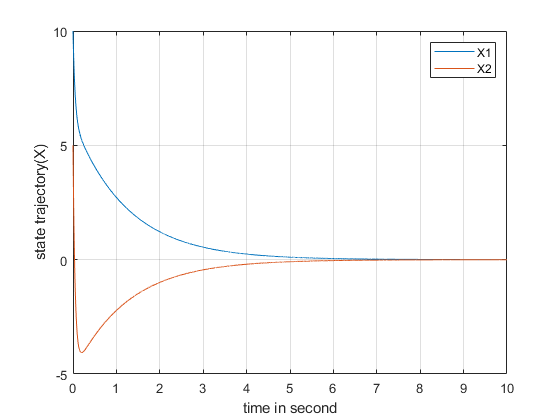



u = zeros(length(t), 1);
x = zeros(length(t), 2);
y = zeros(length(t), 1);
x(1,:) = x0';
u(1) = -K*(x(1,:))';
y(1) = C*(x(1,:))';
for i=2:length(t)
    
    xx0 = (reshape(x(i-1,:),size(x0)));
    xx = xx0;
    xx_dot = A*xx + B*(u(i-1,:)');
    k1 = dt*xx_dot;
    
    xx = xx0 + k1./2;
    xx_dot = A*xx + B*(u(i-1,:)');
    k2 = dt*xx_dot;
    
    xx = xx0 + k2./2;
    xx_dot = A*xx + B*(u(i-1,:)');
    k3 = dt*xx_dot;
    
    xx = xx0 + k3;
    xx_dot = A*xx + B*(u(i-1,:)');
    k4 = dt*xx_dot;
    
    xx = xx0 + k1./6 + k2./3 + k3./3 + k4./6;
    
    x(i,:) = xx(:);
    u(i,:) = -K*(x(i,:))';
    y(i) = C*(x(i,:))';
end
figure
plot(t,x(:,1))
hold on;
plot(t,x(:,2))
grid on
xlabel('time in second')
ylabel('state trajectory(X)')
legend('X1','X2')

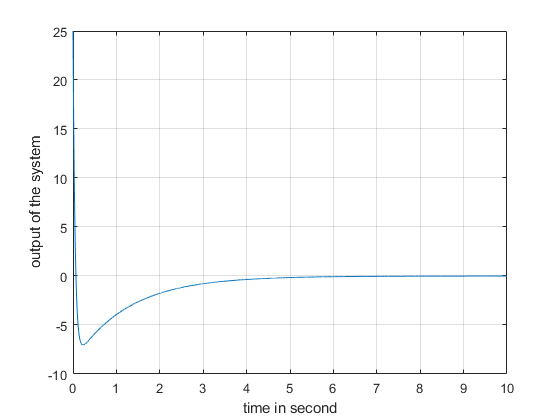

figure
plot(t,y)
grid on
xlabel('time in second')
ylabel('output of the system')

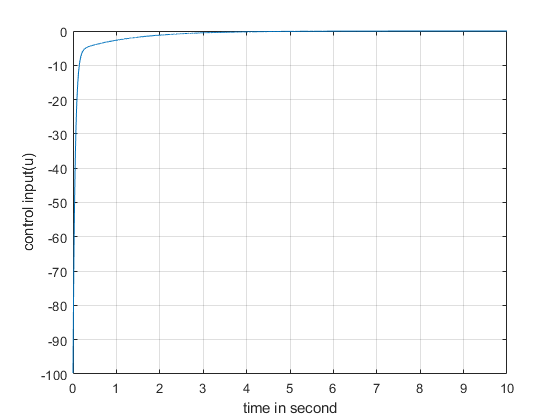

figure
plot(t,u)
grid on;
xlabel('time in second')
ylabel('control input(u)')

## **d)**

Plot of state trajectory and control signal of the cloosed loop system is shown above.

o = obsv(A,C)

o =      1     3
     4    -5


p = rank(o)

p = 2

Q=[5 0;0 50]

Q =      5     0
     0    50


L = lqr(A',C',Q,r,0)

L =    18.5268   16.2731


## **e)**

The observer is : X_dot = AX_ + Bu + L(y-y_) and y_ = CX_

The observer gain L is given above.

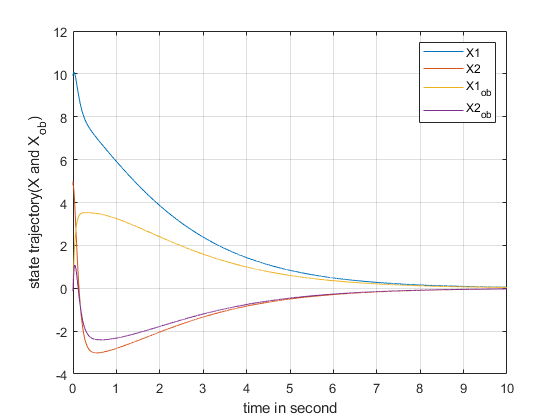

u1 = zeros(length(t), 1);
x1 = zeros(length(t), 2);
y1 = zeros(length(t), 1);
x1(1,:) = x0';
u1(1) = -K*(x1(1,:))';
x_ob = zeros(length(t), 2);
y1(1) = C*(x1(1,:))';
for i=2:length(t)
    
    xx0 = (reshape(x1(i-1,:),size(x0)));
    xx = xx0;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k1 = dt*xx_dot;
    
    xx = xx0 + k1./2;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k2 = dt*xx_dot;
    
    xx = xx0 + k2./2;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k3 = dt*xx_dot;
    
    xx = xx0 + k3;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k4 = dt*xx_dot;
    
    xx = xx0 + k1./6 + k2./3 + k3./3 + k4./6;
    
    x1(i,:) = xx(:);
    %%%%
    xx0 = (reshape(x_ob(i-1,:),size(x0)));
    xx = xx0;
    xx_dot = A*xx + B*(u1(i-1,:)') + L'*(C*x1(i-1,:)' - C*x_ob(i-1,:)');
    k1 = dt*xx_dot;
    
    xx = xx0 + k1./2;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k2 = dt*xx_dot;
    
    xx = xx0 + k2./2;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k3 = dt*xx_dot;
    
    xx = xx0 + k3;
    xx_dot = A*xx + B*(u1(i-1,:)');
    k4 = dt*xx_dot;
    
    xx = xx0 + k1./6 + k2./3 + k3./3 + k4./6;
    x_ob(i,:) = xx(:);
    u1(i,:) = -K*(x_ob(i,:))';
    y1(i) = C*(x1(i,:))';
end
figure
plot(t,x1(:,1))
hold on;
plot(t,x1(:,2))
plot(t,x_ob(:,1))
hold on;
plot(t,x_ob(:,2))
grid on
xlabel('time in second')
ylabel('state trajectory(X and X_{ob})')
legend('X1','X2','X1_{ob}','X2_{ob}')

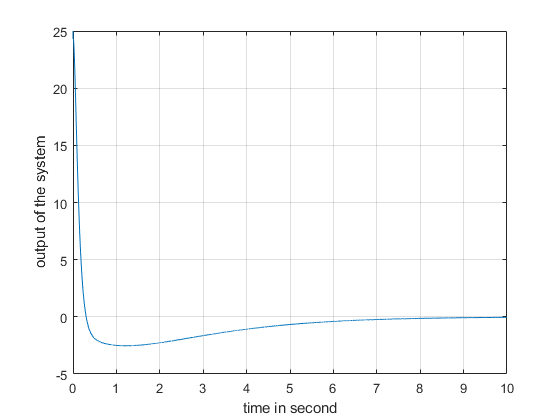

figure
plot(t,y1)
grid on
xlabel('time in second')
ylabel('output of the system')

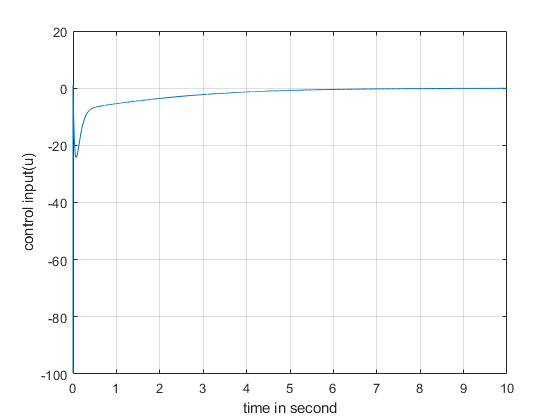

figure
plot(t,u1)
grid on;
xlabel('time in second')
ylabel('control input(u)')

## **f)**

The comparison between part (d) and (e) are given below:

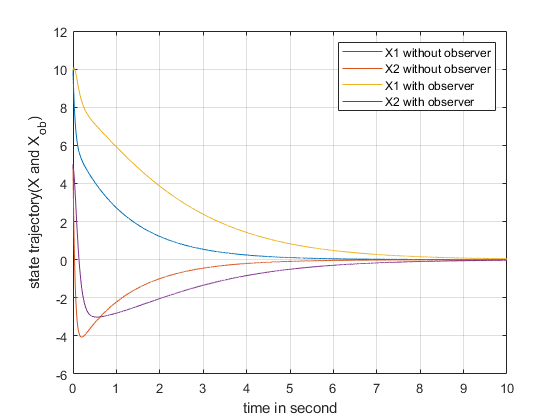

figure
plot(t,x(:,1))
hold on;
plot(t,x(:,2))
plot(t,x1(:,1))
hold on;
plot(t,x1(:,2))
grid on
xlabel('time in second')
ylabel('state trajectory(X and X_{ob})')
legend('X1 without observer','X2 without observer','X1 with observer','X2 with observer')

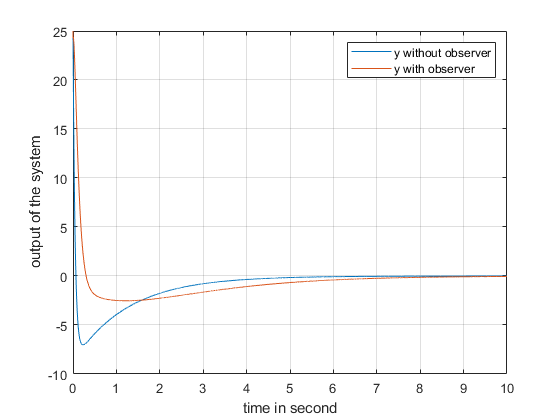

figure
plot(t,y)
hold on
plot(t,y1)
grid on
xlabel('time in second')
ylabel('output of the system')
legend('y without observer','y with observer')

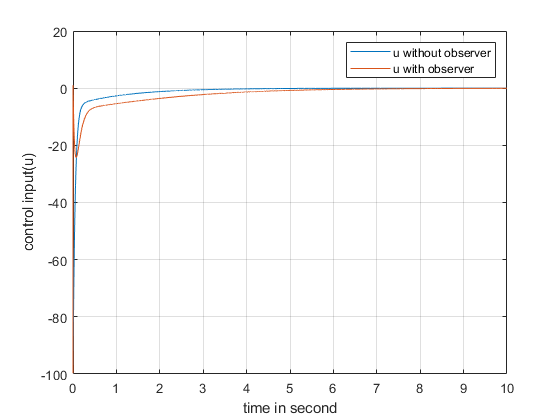

figure
plot(t,u)
hold on
plot(t,u1)
grid on;
xlabel('time in second')
ylabel('control input(u)')
legend('u without observer','u with observer')

## **Remark:** From the plots we see that the performance degrades when we add observer.

## **g)**

The comparisone between the estimated state variable and their actual value are shown below:

figure
plot(t,x1(:,1))
hold on;
plot(t,x1(:,2))
plot(t,x_ob(:,1))
hold on;
plot(t,x_ob(:,2))
grid on
xlabel('time in second')
ylabel('state trajectory(X and X_{ob})')
legend('X1','X2','X1_{ob}','X2_{ob}')

## **Remark: From the plots we see as time goes the estimated state value converges to the real state value.**

**                      %%%%%%%%%%%%%%%%%%%The End%%%%%%%%%%%%%%%%%%%%%%%**